## Gurobi: general Pareto front and time benchmarking

### Uniform weights, step 0.1, alpha=25 (penalty factor)

% Span for uniform weights
span = 0.01:0.01:0.99;

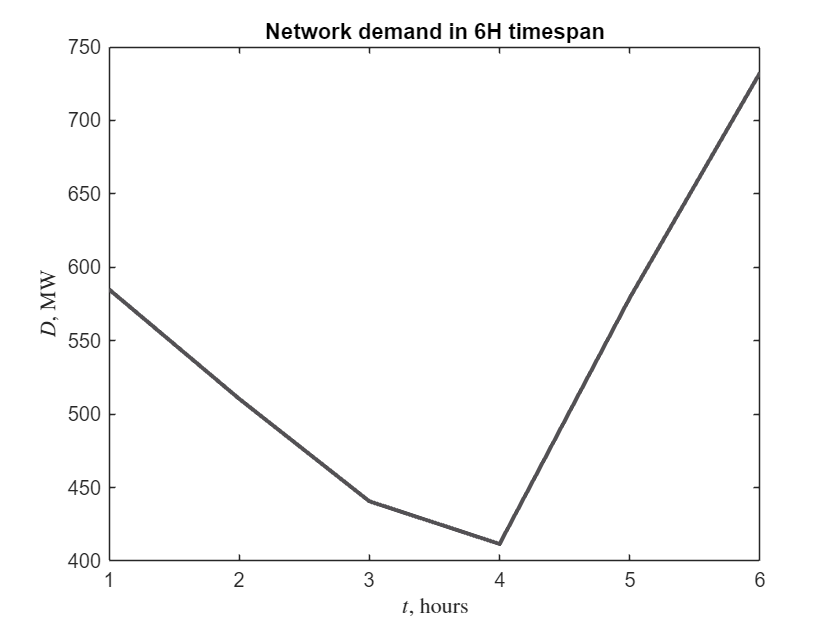


% Placeholders for costs and runtimes
cost_gurobi = zeros(length(span), 2);
runtime_gurobi = zeros(1, length(span));
cost_sedumi = zeros(length(span), 2);
runtime_sedumi = zeros(1, length(span));
objective_gurobi = zeros(1, length(span));
loss = zeros(1, length(span));

% Penalty
alpha = 25;

% Network and schedule size
Nconv = 3;
T = 6;

% Load a network into the workspace
network = network_init(Nconv, T);

demand_color = [83 81 84]/255;

figure()
plot(1:1:T, network.demand, LineWidth=2, Color=demand_color);
title(sprintf('Network demand in %dH timespan', T))
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');

% Run computations for one network, different weights

for i = 1:length(span)
    w2 = span(i);
    w1 = 1 - w2;
    fprintf('Iteration %d: w1=%d, w2=%d\n', i, w1, w2);
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi(i, 1), cost_gurobi(i, 2)] = objective_values(network, alpha, result_gurobi.x);
    runtime_gurobi(i) = result_gurobi.runtime;
    [result_sedumi, runtime_sedumi(i)] = solve_sedumi(network);
    [cost_sedumi(i, 1), cost_sedumi(i, 2)] = objective_values(network, alpha, result_sedumi);
    objective_gurobi(i) = result_gurobi.objval;
    loss(i) = sum(abs(result_gurobi.x - result_sedumi));
end

Iteration 1: w1=9.900000e-01, w2=1.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf4396694
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.940001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.04E-04 0.000
  1 :   1.56E+06 3.87E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.56E+06 1.54E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   7.20E+05 7.04E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.64E+05 3.18E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.84E+04 1.53E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.61E+04 7.41E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.28E+05 3.75E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.47E+05 1.79E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.36E+05 9.19E-07 0.000 

Iteration 2: w1=9.800000e-01, w2=2.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa25474e2
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.880001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.10E-04 0.000
  1 :   1.54E+06 3.91E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.55E+06 1.56E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   7.13E+05 7.11E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.61E+05 3.21E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.81E+04 1.55E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.52E+04 7.49E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.27E+05 3.79E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.46E+05 1.81E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.34E+05 9.28E-07 0.000 

Iteration 3: w1=9.700000e-01, w2=3.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5cd6c1b9
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.820001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.17E-04 0.000
  1 :   1.52E+06 3.95E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.53E+06 1.57E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   7.05E+05 7.18E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.59E+05 3.24E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.79E+04 1.57E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.43E+04 7.57E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.26E+05 3.83E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.44E+05 1.83E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.33E+05 9.38E-07 0.000 

Iteration 4: w1=9.600000e-01, w2=4.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf3a19ead
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.760001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.23E-04 0.000
  1 :   1.51E+06 3.99E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.52E+06 1.59E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.98E+05 7.26E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.56E+05 3.28E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.76E+04 1.58E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.34E+04 7.65E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.24E+05 3.87E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.43E+05 1.85E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.32E+05 9.48E-07 0.000 

Iteration 5: w1=9.500000e-01, w2=5.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x20f22a7e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.700001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.30E-04 0.000
  1 :   1.49E+06 4.03E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.50E+06 1.61E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.91E+05 7.34E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.53E+05 3.31E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.74E+04 1.60E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.24E+04 7.73E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.23E+05 3.91E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.41E+05 1.87E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.30E+05 9.58E-07 0.000 

Iteration 6: w1=9.400000e-01, w2=6.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x1f24e081
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.640001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.36E-04 0.000
  1 :   1.48E+06 4.07E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.48E+06 1.63E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.83E+05 7.41E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.51E+05 3.34E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.72E+04 1.62E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.15E+04 7.81E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.22E+05 3.95E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.40E+05 1.89E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.29E+05 9.68E-07 0.000 

Iteration 7: w1=9.300000e-01, w2=7.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5b6b9000
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.580001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.43E-04 0.000
  1 :   1.46E+06 4.12E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.47E+06 1.64E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.76E+05 7.49E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.48E+05 3.38E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.69E+04 1.63E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -9.06E+04 7.89E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.21E+05 3.99E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.39E+05 1.91E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.28E+05 9.78E-07 0.000 

Iteration 8: w1=9.200000e-01, w2=8.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x58bd2df2
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.520001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.50E-04 0.000
  1 :   1.45E+06 4.16E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.45E+06 1.66E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.69E+05 7.58E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.45E+05 3.42E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.67E+04 1.65E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.97E+04 7.98E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.19E+05 4.04E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.37E+05 1.93E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.26E+05 9.89E-07 0.000 

Iteration 9: w1=9.100000e-01, w2=9.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9fc957ac
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.460001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.57E-04 0.000
  1 :   1.43E+06 4.21E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.44E+06 1.68E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.61E+05 7.66E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.42E+05 3.46E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.64E+04 1.67E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.88E+04 8.07E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.18E+05 4.08E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.36E+05 1.95E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.25E+05 1.00E-06 0.000 

Iteration 10: w1=9.000000e-01, w2=1.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc2270a0c
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.400001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.65E-04 0.000
  1 :   1.41E+06 4.25E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.42E+06 1.70E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.54E+05 7.74E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.40E+05 3.49E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.62E+04 1.69E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.78E+04 8.16E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.17E+05 4.13E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.34E+05 1.97E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.24E+05 1.01E-06 0.000 

Iteration 11: w1=8.900000e-01, w2=1.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x77859c7e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.340001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.72E-04 0.000
  1 :   1.40E+06 4.30E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.40E+06 1.72E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.47E+05 7.83E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.37E+05 3.53E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.59E+04 1.71E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.69E+04 8.25E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.16E+05 4.17E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.33E+05 2.00E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.22E+05 1.02E-06 0.000 

Iteration 12: w1=8.800000e-01, w2=1.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc88cc85d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.280001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.80E-04 0.000
  1 :   1.38E+06 4.35E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.39E+06 1.74E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.39E+05 7.92E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.34E+05 3.57E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.57E+04 1.73E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.60E+04 8.34E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.14E+05 4.22E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.31E+05 2.02E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.21E+05 1.03E-06 0.000 

Iteration 13: w1=8.700000e-01, w2=1.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9e61290e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.220001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.87E-04 0.000
  1 :   1.37E+06 4.40E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.37E+06 1.76E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.32E+05 8.01E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.31E+05 3.61E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.55E+04 1.75E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.51E+04 8.44E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.13E+05 4.27E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.30E+05 2.04E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.20E+05 1.05E-06 0.000 

Iteration 14: w1=8.600000e-01, w2=1.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x772ad8e1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.160001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.95E-04 0.000
  1 :   1.35E+06 4.45E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.36E+06 1.78E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.25E+05 8.10E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.29E+05 3.66E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.52E+04 1.77E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.41E+04 8.53E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.12E+05 4.32E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.28E+05 2.07E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.18E+05 1.06E-06 0.000 

Iteration 15: w1=8.500000e-01, w2=1.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x2fd27811
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.100001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.04E-04 0.000
  1 :   1.34E+06 4.50E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.34E+06 1.80E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.17E+05 8.20E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.26E+05 3.70E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.50E+04 1.79E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.32E+04 8.64E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.11E+05 4.37E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.27E+05 2.09E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.17E+05 1.07E-06 0.000 

Iteration 16: w1=8.400000e-01, w2=1.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xd12d1190
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.040001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.12E-04 0.000
  1 :   1.32E+06 4.56E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.33E+06 1.82E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.10E+05 8.30E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.23E+05 3.74E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.47E+04 1.81E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.23E+04 8.74E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.09E+05 4.42E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.26E+05 2.11E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.16E+05 1.08E-06 0.000 

Iteration 17: w1=8.300000e-01, w2=1.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf2360ac7
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.980001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.21E-04 0.000
  1 :   1.30E+06 4.61E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.31E+06 1.84E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   6.03E+05 8.40E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.21E+05 3.79E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.45E+04 1.83E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.14E+04 8.84E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.08E+05 4.47E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.24E+05 2.14E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.14E+05 1.10E-06 0.000 

Iteration 18: w1=8.200000e-01, w2=1.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xd17243ac
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.920001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.29E-04 0.000
  1 :   1.29E+06 4.67E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.29E+06 1.86E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.95E+05 8.50E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.18E+05 3.83E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.43E+04 1.85E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -8.05E+04 8.95E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.07E+05 4.53E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.23E+05 2.17E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.13E+05 1.11E-06 0.000 

Iteration 19: w1=8.100000e-01, w2=1.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x7d1cea6c
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.860001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.38E-04 0.000
  1 :   1.27E+06 4.73E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.28E+06 1.89E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.88E+05 8.60E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.15E+05 3.88E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.40E+04 1.88E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.95E+04 9.06E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.06E+05 4.58E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.21E+05 2.19E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.12E+05 1.12E-06 0.000 

Iteration 20: w1=8.000000e-01, w2=2.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x3649f430
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.800001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.48E-04 0.000
  1 :   1.26E+06 4.79E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.26E+06 1.91E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.81E+05 8.71E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.12E+05 3.93E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.38E+04 1.90E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.86E+04 9.18E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.04E+05 4.64E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.20E+05 2.22E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.10E+05 1.14E-06 0.000 

Iteration 21: w1=7.900000e-01, w2=2.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x26ff2d64
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.740001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.57E-04 0.000
  1 :   1.24E+06 4.85E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.25E+06 1.93E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.73E+05 8.82E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.10E+05 3.98E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.35E+04 1.92E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.77E+04 9.29E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.03E+05 4.70E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.18E+05 2.25E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.09E+05 1.15E-06 0.000 

Iteration 22: w1=7.800000e-01, w2=2.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xed86331e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.680001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.67E-04 0.000
  1 :   1.23E+06 4.91E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.23E+06 1.96E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.66E+05 8.93E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.07E+05 4.03E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.33E+04 1.95E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.68E+04 9.41E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.02E+05 4.76E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.17E+05 2.28E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.08E+05 1.17E-06 0.000 

Iteration 23: w1=7.700000e-01, w2=2.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa4ff4330
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.620001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.77E-04 0.000
  1 :   1.21E+06 4.97E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.21E+06 1.98E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.59E+05 9.05E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.04E+05 4.08E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.30E+04 1.97E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.59E+04 9.53E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.01E+05 4.82E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.15E+05 2.31E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.06E+05 1.18E-06 0.000 

Iteration 24: w1=7.600000e-01, w2=2.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb7c56c7d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.560001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.87E-04 0.000
  1 :   1.19E+06 5.04E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.20E+06 2.01E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.51E+05 9.17E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.01E+05 4.14E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.28E+04 2.00E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.49E+04 9.66E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.94E+04 4.89E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.14E+05 2.34E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.05E+05 1.20E-06 0.000 

Iteration 25: w1=7.500000e-01, w2=2.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xe340f760
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.500001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.97E-04 0.000
  1 :   1.18E+06 5.10E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.18E+06 2.04E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.44E+05 9.29E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.99E+05 4.19E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.26E+04 2.03E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.40E+04 9.79E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.82E+04 4.95E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.12E+05 2.37E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.04E+05 1.21E-06 0.000 

Iteration 26: w1=7.400000e-01, w2=2.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xef22b750
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.440001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.08E-04 0.000
  1 :   1.16E+06 5.17E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.17E+06 2.06E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.37E+05 9.42E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.96E+05 4.25E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.23E+04 2.05E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.31E+04 9.92E-06 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.69E+04 5.02E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.11E+05 2.40E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.02E+05 1.23E-06 0.000 

Iteration 27: w1=7.300000e-01, w2=2.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0b76e0f1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.380001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.19E-04 0.000
  1 :   1.15E+06 5.24E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.15E+06 2.09E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.29E+05 9.55E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.93E+05 4.31E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.21E+04 2.08E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.22E+04 1.01E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.56E+04 5.09E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.10E+05 2.43E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.01E+05 1.25E-06 0.000 

Iteration 28: w1=7.200000e-01, w2=2.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf89544e5
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.320001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.31E-04 0.000
  1 :   1.13E+06 5.32E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.14E+06 2.12E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.22E+05 9.68E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.90E+05 4.37E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.18E+04 2.11E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.13E+04 1.02E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.44E+04 5.16E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.08E+05 2.47E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.97E+04 1.26E-06 0.000 

Iteration 29: w1=7.100000e-01, w2=2.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x41ed7c61
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.260001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.42E-04 0.000
  1 :   1.12E+06 5.39E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.12E+06 2.15E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.15E+05 9.82E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.88E+05 4.43E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.16E+04 2.14E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -7.03E+04 1.03E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.31E+04 5.23E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.07E+05 2.50E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.84E+04 1.28E-06 0.000 

Iteration 30: w1=7.000000e-01, w2=3.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x57d2196f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.200001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.54E-04 0.000
  1 :   1.10E+06 5.47E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.10E+06 2.18E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.07E+05 9.96E-05 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.85E+05 4.49E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.13E+04 2.17E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.94E+04 1.05E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.19E+04 5.31E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.05E+05 2.54E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.70E+04 1.30E-06 0.000 

Iteration 31: w1=6.900000e-01, w2=3.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x28768dba
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.140001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.67E-04 0.000
  1 :   1.08E+06 5.55E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.09E+06 2.21E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   5.00E+05 1.01E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.82E+05 4.56E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.11E+04 2.20E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.85E+04 1.06E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -9.06E+04 5.38E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.04E+05 2.57E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.57E+04 1.32E-06 0.000 

Iteration 32: w1=6.800000e-01, w2=3.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9226f2ce
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.080001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.79E-04 0.000
  1 :   1.07E+06 5.63E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.07E+06 2.25E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.93E+05 1.02E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.80E+05 4.62E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.09E+04 2.23E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.76E+04 1.08E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.94E+04 5.46E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.02E+05 2.61E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.44E+04 1.34E-06 0.000 

Iteration 33: w1=6.700000e-01, w2=3.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x31578f9a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.020001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.93E-04 0.000
  1 :   1.05E+06 5.71E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.06E+06 2.28E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.85E+05 1.04E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.77E+05 4.69E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.06E+04 2.27E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.66E+04 1.10E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.81E+04 5.54E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -1.01E+05 2.65E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.30E+04 1.36E-06 0.000 

Iteration 34: w1=6.600000e-01, w2=3.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x82a9fd08
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.960001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.06E-04 0.000
  1 :   1.04E+06 5.80E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.04E+06 2.31E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.78E+05 1.06E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.74E+05 4.76E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.04E+04 2.30E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.57E+04 1.11E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.69E+04 5.63E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.95E+04 2.69E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.17E+04 1.38E-06 0.000 

Iteration 35: w1=6.500000e-01, w2=3.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x854c06a7
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.900001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.20E-04 0.000
  1 :   1.02E+06 5.89E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.02E+06 2.35E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.71E+05 1.07E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.71E+05 4.84E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.01E+04 2.34E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.48E+04 1.13E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.56E+04 5.71E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.80E+04 2.73E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -9.04E+04 1.40E-06 0.000 

Iteration 36: w1=6.400000e-01, w2=3.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x73acd02a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.840001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.34E-04 0.000
  1 :   1.01E+06 5.98E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.01E+06 2.39E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.63E+05 1.09E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.69E+05 4.91E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   9.88E+03 2.37E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.39E+04 1.15E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.44E+04 5.80E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.66E+04 2.78E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.90E+04 1.42E-06 0.000 

Iteration 37: w1=6.300000e-01, w2=3.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x419a16d4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.780001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.49E-04 0.000
  1 :   9.90E+05 6.08E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.93E+05 2.42E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.56E+05 1.11E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.66E+05 4.99E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   9.64E+03 2.41E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.30E+04 1.17E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.31E+04 5.89E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.51E+04 2.82E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.77E+04 1.44E-06 0.000 

Iteration 38: w1=6.200000e-01, w2=3.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf2654af4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.720001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.65E-04 0.000
  1 :   9.74E+05 6.17E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.77E+05 2.46E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.49E+05 1.12E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.63E+05 5.07E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   9.40E+03 2.45E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.20E+04 1.18E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.18E+04 5.99E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.37E+04 2.87E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.63E+04 1.47E-06 0.000 

Iteration 39: w1=6.100000e-01, w2=3.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x265d625d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.660001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.80E-04 0.000
  1 :   9.58E+05 6.28E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.61E+05 2.50E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.41E+05 1.14E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.60E+05 5.15E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   9.16E+03 2.49E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.11E+04 1.20E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -8.06E+04 6.09E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.22E+04 2.91E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.50E+04 1.49E-06 0.000 

Iteration 40: w1=6.000000e-01, w2=4.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xd4dc8e8e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.600001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.97E-04 0.000
  1 :   9.42E+05 6.38E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.45E+05 2.55E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.34E+05 1.16E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.58E+05 5.24E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   8.91E+03 2.53E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -6.02E+04 1.22E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.93E+04 6.19E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -9.08E+04 2.96E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.37E+04 1.52E-06 0.000 

Iteration 41: w1=5.900000e-01, w2=4.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9e705e72
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.540001e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.01E-03 0.000
  1 :   9.27E+05 6.49E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.29E+05 2.59E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.27E+05 1.18E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.55E+05 5.33E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   8.67E+03 2.57E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.93E+04 1.24E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.81E+04 6.29E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.93E+04 3.01E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.23E+04 1.54E-06 0.000 

Iteration 42: w1=5.800000e-01, w2=4.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xbdc1151f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.480000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.03E-03 0.000
  1 :   9.11E+05 6.60E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.14E+05 2.63E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.19E+05 1.20E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.52E+05 5.42E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   8.43E+03 2.62E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.84E+04 1.27E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.68E+04 6.40E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.79E+04 3.06E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -8.10E+04 1.57E-06 0.000 

Iteration 43: w1=5.700000e-01, w2=4.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0221f3fd
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.420000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.05E-03 0.000
  1 :   8.95E+05 6.72E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.98E+05 2.68E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.12E+05 1.22E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.49E+05 5.52E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   8.19E+03 2.66E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.74E+04 1.29E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.56E+04 6.52E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.64E+04 3.12E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.97E+04 1.60E-06 0.000 

Iteration 44: w1=5.600000e-01, w2=4.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x98804e59
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.360000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.07E-03 0.000
  1 :   8.79E+05 6.84E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.82E+05 2.73E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   4.05E+05 1.24E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.47E+05 5.61E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   7.94E+03 2.71E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.65E+04 1.31E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.43E+04 6.63E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.50E+04 3.17E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.83E+04 1.62E-06 0.000 

Iteration 45: w1=5.500000e-01, w2=4.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x2d5dcdca
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.300000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.09E-03 0.000
  1 :   8.64E+05 6.96E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.66E+05 2.78E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.97E+05 1.27E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.44E+05 5.72E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   7.70E+03 2.76E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.56E+04 1.33E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.31E+04 6.75E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.35E+04 3.23E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.70E+04 1.65E-06 0.000 

Iteration 46: w1=5.400000e-01, w2=4.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x8319bbb4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.240000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.11E-03 0.000
  1 :   8.48E+05 7.09E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.50E+05 2.83E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.90E+05 1.29E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.41E+05 5.82E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   7.46E+03 2.81E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.47E+04 1.36E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.18E+04 6.88E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.21E+04 3.29E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.57E+04 1.68E-06 0.000 

Iteration 47: w1=5.300000e-01, w2=4.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xe465871d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.180000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.13E-03 0.000
  1 :   8.32E+05 7.22E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.34E+05 2.88E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.83E+05 1.31E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.39E+05 5.93E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   7.22E+03 2.87E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.37E+04 1.38E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -7.06E+04 7.01E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -8.06E+04 3.35E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.43E+04 1.72E-06 0.000 

Iteration 48: w1=5.200000e-01, w2=4.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x00da9621
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.120000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.15E-03 0.000
  1 :   8.16E+05 7.36E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.19E+05 2.94E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.75E+05 1.34E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.36E+05 6.05E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   6.97E+03 2.92E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.28E+04 1.41E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.93E+04 7.14E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.92E+04 3.42E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.30E+04 1.75E-06 0.000 

Iteration 49: w1=5.100000e-01, w2=4.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x4019dc2c
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.060000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.17E-03 0.000
  1 :   8.01E+05 7.51E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   8.03E+05 3.00E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.68E+05 1.37E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.33E+05 6.16E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   6.73E+03 2.98E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.19E+04 1.44E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.81E+04 7.28E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.77E+04 3.48E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.17E+04 1.78E-06 0.000 

Iteration 50: w1=5.000000e-01, w2=5.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf1924f73
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.000000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.20E-03 0.000
  1 :   7.85E+05 7.66E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   7.87E+05 3.05E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.61E+05 1.39E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.30E+05 6.29E-05 0.000 0.4511 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   6.49E+03 3.04E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.10E+04 1.47E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.68E+04 7.43E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.63E+04 3.55E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -7.03E+04 1.82E-06 0.000 

Iteration 51: w1=4.900000e-01, w2=5.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb88feea1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.940000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.22E-03 0.000
  1 :   7.69E+05 7.81E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   7.71E+05 3.12E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.53E+05 1.42E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.28E+05 6.42E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   6.25E+03 3.10E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -5.01E+04 1.50E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.55E+04 7.58E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.48E+04 3.63E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.90E+04 1.86E-06 0.000 

Iteration 52: w1=4.800000e-01, w2=5.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xdb25c689
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.880000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.25E-03 0.000
  1 :   7.53E+05 7.98E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   7.55E+05 3.18E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.46E+05 1.45E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.25E+05 6.55E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   6.01E+03 3.16E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.91E+04 1.53E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.43E+04 7.74E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.34E+04 3.70E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.76E+04 1.90E-06 0.000 

Iteration 53: w1=4.700000e-01, w2=5.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa591a303
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.820000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.27E-03 0.000
  1 :   7.38E+05 8.15E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   7.39E+05 3.25E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.39E+05 1.48E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.22E+05 6.69E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   5.76E+03 3.23E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.82E+04 1.56E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.30E+04 7.90E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.19E+04 3.78E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.63E+04 1.94E-06 0.000 

Iteration 54: w1=4.600000e-01, w2=5.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf0288bcc
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.760000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.30E-03 0.000
  1 :   7.22E+05 8.32E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   7.24E+05 3.32E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.31E+05 1.51E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.19E+05 6.83E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   5.52E+03 3.30E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.73E+04 1.60E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.18E+04 8.07E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -7.05E+04 3.86E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.50E+04 1.98E-06 0.000 

Iteration 55: w1=4.500000e-01, w2=5.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5e779d42
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.700000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.33E-03 0.000
  1 :   7.06E+05 8.51E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   7.08E+05 3.39E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.24E+05 1.55E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.17E+05 6.99E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   5.28E+03 3.38E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.64E+04 1.63E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -6.05E+04 8.25E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.90E+04 3.95E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.36E+04 2.02E-06 0.000 

Iteration 56: w1=4.400000e-01, w2=5.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x3608f6cb
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 4e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.640000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.36E-03 0.000
  1 :   6.90E+05 8.70E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   6.92E+05 3.47E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.17E+05 1.58E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.14E+05 7.15E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   5.04E+03 3.45E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.55E+04 1.67E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.93E+04 8.44E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.76E+04 4.04E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.23E+04 2.07E-06 0.000 

Iteration 57: w1=4.300000e-01, w2=5.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x01a3e982
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 4e+03]
  QObjective range [3e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.580000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.39E-03 0.000
  1 :   6.75E+05 8.90E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   6.76E+05 3.55E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.09E+05 1.62E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.11E+05 7.31E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   4.79E+03 3.53E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.45E+04 1.71E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.80E+04 8.64E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.61E+04 4.13E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -6.10E+04 2.12E-06 0.000 

Iteration 58: w1=4.200000e-01, w2=5.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa40f1fd3
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [3e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.520000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.42E-03 0.000
  1 :   6.59E+05 9.11E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   6.60E+05 3.64E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   3.02E+05 1.66E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.08E+05 7.49E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   4.55E+03 3.62E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.36E+04 1.75E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.68E+04 8.84E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.47E+04 4.23E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.96E+04 2.17E-06 0.000 

Iteration 59: w1=4.100000e-01, w2=5.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa6eb7f66
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [3e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.460000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.46E-03 0.000
  1 :   6.43E+05 9.34E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   6.44E+05 3.73E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.95E+05 1.70E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.06E+05 7.67E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   4.31E+03 3.70E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.27E+04 1.79E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.55E+04 9.06E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.32E+04 4.33E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.83E+04 2.22E-06 0.000 

Iteration 60: w1=4.000000e-01, w2=6.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5efd6d75
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.400000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.49E-03 0.000
  1 :   6.28E+05 9.57E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   6.29E+05 3.82E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.87E+05 1.74E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.03E+05 7.86E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   4.07E+03 3.80E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.18E+04 1.84E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.43E+04 9.28E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.18E+04 4.44E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.70E+04 2.27E-06 0.000 

Iteration 61: w1=3.900000e-01, w2=6.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0f73e357
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.340000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.53E-03 0.000
  1 :   6.12E+05 9.82E-04 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   6.13E+05 3.92E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.80E+05 1.79E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   1.00E+05 8.06E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   3.82E+03 3.89E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -4.08E+04 1.88E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.30E+04 9.52E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -6.03E+04 4.56E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.56E+04 2.33E-06 0.000 

Iteration 62: w1=3.800000e-01, w2=6.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5479b296
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.280000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.57E-03 0.000
  1 :   5.96E+05 1.01E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.97E+05 4.02E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.73E+05 1.83E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   9.76E+04 8.27E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   3.58E+03 4.00E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.99E+04 1.93E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.17E+04 9.77E-06 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.89E+04 4.68E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.43E+04 2.39E-06 0.000 

Iteration 63: w1=3.700000e-01, w2=6.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x42610007
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.220000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.62E-03 0.000
  1 :   5.80E+05 1.03E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.81E+05 4.13E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.65E+05 1.88E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   9.48E+04 8.50E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   3.34E+03 4.10E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.90E+04 1.98E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -5.05E+04 1.00E-05 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.74E+04 4.80E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.30E+04 2.46E-06 0.000 

Iteration 64: w1=3.600000e-01, w2=6.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x8adc61fd
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.160000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.66E-03 0.000
  1 :   5.65E+05 1.06E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.65E+05 4.24E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.58E+05 1.94E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   9.21E+04 8.73E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   3.10E+03 4.22E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.81E+04 2.04E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.92E+04 1.03E-05 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.60E+04 4.93E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.16E+04 2.53E-06 0.000 

Iteration 65: w1=3.500000e-01, w2=6.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9ba78d7b
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.100000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.71E-03 0.000
  1 :   5.49E+05 1.09E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.49E+05 4.36E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.51E+05 1.99E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   8.94E+04 8.98E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   2.86E+03 4.34E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.72E+04 2.10E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.80E+04 1.06E-05 0.000 0.5059 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.45E+04 5.08E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -5.03E+04 2.60E-06 0.000 

Iteration 66: w1=3.400000e-01, w2=6.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x7cbe101b
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 3e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.040000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.76E-03 0.000
  1 :   5.33E+05 1.13E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.34E+05 4.49E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.43E+05 2.05E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   8.66E+04 9.25E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   2.61E+03 4.47E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.62E+04 2.16E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.67E+04 1.09E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.31E+04 5.23E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.89E+04 2.68E-06 0.000 

Iteration 67: w1=3.300000e-01, w2=6.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc4a34535
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 3e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.980000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.81E-03 0.000
  1 :   5.17E+05 1.16E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.18E+05 4.63E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.36E+05 2.11E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   8.39E+04 9.53E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   2.37E+03 4.60E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.53E+04 2.22E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.55E+04 1.13E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.16E+04 5.38E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.76E+04 2.76E-06 0.000 

Iteration 68: w1=3.200000e-01, w2=6.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x31e49620
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.920000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.87E-03 0.000
  1 :   5.02E+05 1.20E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   5.02E+05 4.77E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.29E+05 2.18E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   8.12E+04 9.82E-05 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   2.13E+03 4.75E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.4E+01
  6 :  -3.44E+04 2.29E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.42E+04 1.16E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -5.02E+04 5.55E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.63E+04 2.84E-06 0.000 

Iteration 69: w1=3.100000e-01, w2=6.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x170450d9
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.860000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.93E-03 0.000
  1 :   4.86E+05 1.23E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   4.86E+05 4.93E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.21E+05 2.25E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   7.84E+04 1.01E-04 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.89E+03 4.90E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -3.35E+04 2.37E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.30E+04 1.20E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.88E+04 5.73E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.49E+04 2.93E-06 0.000 

Iteration 70: w1=3.000000e-01, w2=7.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc9f755e5
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.800000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.99E-03 0.000
  1 :   4.70E+05 1.28E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   4.70E+05 5.09E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.14E+05 2.32E-04 0.000 0.4562 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   7.57E+04 1.05E-04 0.000 0.4512 0.9000 0.9000   0.39  1  1  1.5E+02
  5 :   1.64E+03 5.06E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -3.26E+04 2.45E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.17E+04 1.24E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.73E+04 5.92E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.36E+04 3.03E-06 0.000 

Iteration 71: w1=2.900000e-01, w2=7.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x32afed07
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.740000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.06E-03 0.000
  1 :   4.54E+05 1.32E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   4.54E+05 5.27E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   2.07E+05 2.40E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   7.30E+04 1.08E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :   1.40E+03 5.24E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -3.16E+04 2.53E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -4.05E+04 1.28E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.59E+04 6.13E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.23E+04 3.14E-06 0.000 

Iteration 72: w1=2.800000e-01, w2=7.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa17f7f13
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.680000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.14E-03 0.000
  1 :   4.39E+05 1.37E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   4.39E+05 5.45E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.99E+05 2.49E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   7.02E+04 1.12E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :   1.16E+03 5.42E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -3.07E+04 2.62E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.92E+04 1.33E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.44E+04 6.34E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -4.09E+04 3.25E-06 0.000 

Iteration 73: w1=2.700000e-01, w2=7.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x75e2d679
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.620000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.21E-03 0.000
  1 :   4.23E+05 1.42E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   4.23E+05 5.66E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.92E+05 2.58E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   6.75E+04 1.16E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :   9.19E+02 5.63E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.98E+04 2.72E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.80E+04 1.38E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.30E+04 6.58E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.96E+04 3.37E-06 0.000 

Iteration 74: w1=2.600000e-01, w2=7.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x3a681495
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.560000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.30E-03 0.000
  1 :   4.07E+05 1.47E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   4.07E+05 5.87E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.85E+05 2.68E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   6.48E+04 1.21E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :   6.77E+02 5.84E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.89E+04 2.82E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.67E+04 1.43E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.15E+04 6.83E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.83E+04 3.50E-06 0.000 

Iteration 75: w1=2.500000e-01, w2=7.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xefea506a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.500000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.39E-03 0.000
  1 :   3.91E+05 1.53E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   3.91E+05 6.11E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.77E+05 2.79E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   6.20E+04 1.26E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :   4.35E+02 6.08E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.79E+04 2.94E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.54E+04 1.49E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -4.01E+04 7.11E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.69E+04 3.64E-06 0.000 

Iteration 76: w1=2.400000e-01, w2=7.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x606a2527
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.440000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.49E-03 0.000
  1 :   3.76E+05 1.59E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   3.75E+05 6.36E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.70E+05 2.90E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   5.93E+04 1.31E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :   1.93E+02 6.33E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.70E+04 3.06E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.42E+04 1.55E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -3.86E+04 7.40E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.56E+04 3.79E-06 0.000 

Iteration 77: w1=2.300000e-01, w2=7.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x8af998df
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.380000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.60E-03 0.000
  1 :   3.60E+05 1.66E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   3.60E+05 6.64E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.63E+05 3.03E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   5.66E+04 1.37E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -4.82E+01 6.60E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.61E+04 3.19E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.29E+04 1.61E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -3.72E+04 7.72E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.43E+04 3.96E-06 0.000 

Iteration 78: w1=2.200000e-01, w2=7.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc35c3c7d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.320000e+11
Presolve removed 259 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.72E-03 0.000
  1 :   3.44E+05 1.74E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   3.44E+05 6.94E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.55E+05 3.17E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   5.39E+04 1.43E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -2.90E+02 6.90E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.52E+04 3.34E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.17E+04 1.69E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -3.57E+04 8.08E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.29E+04 4.14E-06 0.000 

Iteration 79: w1=2.100000e-01, w2=7.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9fdf75a0
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.260000e+11
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.85E-03 0.000
  1 :   3.28E+05 1.82E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   3.28E+05 7.27E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.48E+05 3.32E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   5.11E+04 1.50E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -5.31E+02 7.23E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.43E+04 3.50E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -3.04E+04 1.77E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -3.43E+04 8.46E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.16E+04 4.33E-06 0.000 

Iteration 80: w1=2.000000e-01, w2=8.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x189ff6df
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.200000e+11
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.99E-03 0.000
  1 :   3.13E+05 1.91E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   3.12E+05 7.64E-04 0.000 0.3990 0.9000 0.9000   1.22  1  1  4.5E+02
  3 :   1.41E+05 3.48E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   4.84E+04 1.57E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -7.73E+02 7.59E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.33E+04 3.67E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.92E+04 1.86E-05 0.000 0.5060 0.9000 0.9000   0.95  1  1  1.9E+01
  8 :  -3.28E+04 8.88E-06 0.000 0.4784 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -3.02E+04 4.55E-06 0.000 

Iteration 81: w1=1.900000e-01, w2=8.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x032bbbc1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.140000e+11
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.15E-03 0.000
  1 :   2.97E+05 2.01E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.96E+05 8.04E-04 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   1.34E+05 3.67E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   4.57E+04 1.65E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -1.01E+03 7.99E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.24E+04 3.86E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.79E+04 1.95E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -3.14E+04 9.35E-06 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.89E+04 4.79E-06 0.000 

Iteration 82: w1=1.800000e-01, w2=8.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x43f58d22
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.080000e+11
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.32E-03 0.000
  1 :   2.81E+05 2.13E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.80E+05 8.48E-04 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   1.26E+05 3.87E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   4.29E+04 1.75E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -1.25E+03 8.44E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.15E+04 4.08E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.67E+04 2.06E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.99E+04 9.87E-06 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.76E+04 5.05E-06 0.000 

Iteration 83: w1=1.700000e-01, w2=8.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x2661a342
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 2e+03]
  QObjective range [1e-04, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.020000e+11
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.52E-03 0.000
  1 :   2.65E+05 2.25E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.65E+05 8.98E-04 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   1.19E+05 4.10E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   4.02E+04 1.85E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -1.50E+03 8.93E-05 0.000 0.4831 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -2.06E+04 4.32E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.54E+04 2.18E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.85E+04 1.05E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.62E+04 5.35E-06 0.000 

Iteration 84: w1=1.600000e-01, w2=8.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xdb62795a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 2e+03]
  QObjective range [1e-04, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 9.600002e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.74E-03 0.000
  1 :   2.50E+05 2.39E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.49E+05 9.54E-04 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   1.12E+05 4.35E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   3.75E+04 1.96E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -1.74E+03 9.49E-05 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.96E+04 4.59E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.42E+04 2.32E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.70E+04 1.11E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.49E+04 5.69E-06 0.000 

Iteration 85: w1=1.500000e-01, w2=8.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9458ab24
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 2e+03]
  QObjective range [9e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 9.000002e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.98E-03 0.000
  1 :   2.34E+05 2.55E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.33E+05 1.02E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   1.04E+05 4.64E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   3.47E+04 2.10E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -1.98E+03 1.01E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.87E+04 4.89E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.29E+04 2.48E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.56E+04 1.18E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.36E+04 6.07E-06 0.000 

Iteration 86: w1=1.400000e-01, w2=8.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0bffaa8f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 1e+03]
  QObjective range [9e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 8.400001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.27E-03 0.000
  1 :   2.18E+05 2.73E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.17E+05 1.09E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   9.69E+04 4.98E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   3.20E+04 2.25E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -2.22E+03 1.08E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.78E+04 5.24E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.16E+04 2.65E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.41E+04 1.27E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.22E+04 6.50E-06 0.000 

Iteration 87: w1=1.300000e-01, w2=8.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x7cf099ab
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 1e+03]
  QObjective range [8e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 7.800001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.60E-03 0.000
  1 :   2.03E+05 2.94E-03 0.000 0.6402 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   2.01E+05 1.17E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   8.95E+04 5.36E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.93E+04 2.42E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -2.46E+03 1.17E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.69E+04 5.65E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -2.04E+04 2.86E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.27E+04 1.37E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -2.09E+04 7.00E-06 0.000 

Iteration 88: w1=1.200000e-01, w2=8.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb3912f74
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 1e+03]
  QObjective range [7e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 7.200001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.98E-03 0.000
  1 :   1.87E+05 3.19E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.85E+05 1.27E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   8.22E+04 5.81E-04 0.000 0.4563 0.9000 0.9000   0.62  1  1  2.5E+02
  4 :   2.66E+04 2.62E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -2.69E+03 1.27E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.60E+04 6.12E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.91E+04 3.10E-05 0.000 0.5060 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -2.12E+04 1.48E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.96E+04 7.58E-06 0.000 

Iteration 89: w1=1.100000e-01, w2=8.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x05fa8636
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 1e+03]
  QObjective range [7e-05, 9e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 6.600001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.43E-03 0.000
  1 :   1.71E+05 3.48E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.70E+05 1.39E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   7.49E+04 6.33E-04 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   2.38E+04 2.86E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -2.93E+03 1.38E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.50E+04 6.67E-05 0.000 0.4833 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.79E+04 3.38E-05 0.000 0.5061 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -1.98E+04 1.62E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.82E+04 8.27E-06 0.000 

Iteration 90: w1=1.000000e-01, w2=9.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb8f11320
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 1e+03]
  QObjective range [6e-05, 8e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 6.000001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.98E-03 0.000
  1 :   1.55E+05 3.83E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.54E+05 1.53E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   6.75E+04 6.97E-04 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   2.11E+04 3.14E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -3.17E+03 1.52E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.41E+04 7.34E-05 0.000 0.4834 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.66E+04 3.71E-05 0.000 0.5061 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -1.83E+04 1.78E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.69E+04 9.10E-06 0.000 

Iteration 91: w1=9.000000e-02, w2=9.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x311bbbe4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 9e+02]
  QObjective range [6e-05, 7e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.400001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.64E-03 0.000
  1 :   1.40E+05 4.25E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.38E+05 1.70E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   6.02E+04 7.74E-04 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   1.84E+04 3.49E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -3.41E+03 1.69E-04 0.000 0.4832 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.32E+04 8.16E-05 0.000 0.4834 0.9000 0.9000   0.52  1  1  4.2E+01
  7 :  -1.54E+04 4.13E-05 0.000 0.5061 0.9000 0.9000   0.94  1  1  1.9E+01
  8 :  -1.69E+04 1.97E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.55E+04 1.01E-05 0.000 

Iteration 92: w1=8.000000e-02, w2=9.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9eba9ac8
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 8e+02]
  QObjective range [5e-05, 6e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.800001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.47E-03 0.000
  1 :   1.24E+05 4.78E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.22E+05 1.91E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   5.29E+04 8.71E-04 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   1.56E+04 3.93E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -3.64E+03 1.90E-04 0.000 0.4833 0.9000 0.9000   0.52  1  1  7.3E+01
  6 :  -1.23E+04 9.18E-05 0.000 0.4834 0.9000 0.9000   0.51  1  1  4.2E+01
  7 :  -1.41E+04 4.64E-05 0.000 0.5061 0.9000 0.9000   0.94  1  1  1.8E+01
  8 :  -1.54E+04 2.22E-05 0.000 0.4783 0.9000 0.9000   0.45  1  1  1.2E+01
  9 :  -1.42E+04 1.14E-05 0.000 

Iteration 93: w1=7.000000e-02, w2=9.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x10bafc1f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-03, 7e+02]
  QObjective range [4e-05, 6e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.200001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.53E-03 0.000
  1 :   1.08E+05 5.46E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   1.06E+05 2.18E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   4.56E+04 9.95E-04 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   1.29E+04 4.49E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.5E+02
  5 :  -3.88E+03 2.17E-04 0.000 0.4833 0.9000 0.9000   0.53  1  1  7.3E+01
  6 :  -1.13E+04 1.05E-04 0.000 0.4834 0.9000 0.9000   0.51  1  1  4.2E+01
  7 :  -1.29E+04 5.31E-05 0.000 0.5062 0.9000 0.9000   0.94  1  1  1.8E+01
  8 :  -1.40E+04 2.54E-05 0.000 0.4783 0.9000 0.9000   0.44  1  1  1.2E+01
  9 :  -1.29E+04 1.30E-05 0.000 

Iteration 94: w1=6.000000e-02, w2=9.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xef4c35a4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-03, 6e+02]
  QObjective range [4e-05, 5e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.600001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.95E-03 0.000
  1 :   9.23E+04 6.37E-03 0.000 0.6403 0.9000 0.9000   1.21  1  1  1.1E+03
  2 :   9.04E+04 2.54E-03 0.000 0.3990 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   3.83E+04 1.16E-03 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   1.02E+04 5.24E-04 0.000 0.4512 0.9000 0.9000   0.40  1  1  1.4E+02
  5 :  -4.10E+03 2.53E-04 0.000 0.4833 0.9000 0.9000   0.53  1  1  7.3E+01
  6 :  -1.04E+04 1.22E-04 0.000 0.4834 0.9000 0.9000   0.51  1  1  4.2E+01
  7 :  -1.16E+04 6.19E-05 0.000 0.5062 0.9000 0.9000   0.94  1  1  1.8E+01
  8 :  -1.25E+04 2.96E-05 0.000 0.4783 0.9000 0.9000   0.44  1  1  1.2E+01
  9 :  -1.15E+04 1.52E-05 0.000 

Iteration 95: w1=5.000000e-02, w2=9.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x75da90f8
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-03, 5e+02]
  QObjective range [3e-05, 4e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.000001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.19E-02 0.000
  1 :   7.66E+04 7.65E-03 0.000 0.6404 0.9000 0.9000   1.22  1  1  1.1E+03
  2 :   7.46E+04 3.05E-03 0.000 0.3991 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   3.09E+04 1.39E-03 0.000 0.4563 0.9000 0.9000   0.63  1  1  2.5E+02
  4 :   7.49E+03 6.28E-04 0.000 0.4512 0.9000 0.9000   0.41  1  1  1.4E+02
  5 :  -4.33E+03 3.04E-04 0.000 0.4834 0.9000 0.9000   0.53  1  1  7.2E+01
  6 :  -9.47E+03 1.47E-04 0.000 0.4834 0.9000 0.9000   0.51  1  1  4.2E+01
  7 :  -1.03E+04 7.43E-05 0.000 0.5063 0.9000 0.9000   0.93  1  1  1.8E+01
  8 :  -1.11E+04 3.55E-05 0.000 0.4782 0.9000 0.9000   0.44  1  1  1.2E+01
  9 :  -1.02E+04 1.82E-05 0.000 

Iteration 96: w1=4.000000e-02, w2=9.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x845a619b
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-04, 4e+02]
  QObjective range [2e-05, 3e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.400001e+10
Presolve removed 258 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.49E-02 0.000
  1 :   6.08E+04 9.55E-03 0.000 0.6404 0.9000 0.9000   1.22  1  1  1.1E+03
  2 :   5.88E+04 3.81E-03 0.000 0.3991 0.9000 0.9000   1.23  1  1  4.5E+02
  3 :   2.36E+04 1.74E-03 0.000 0.4563 0.9000 0.9000   0.64  1  1  2.5E+02
  4 :   4.79E+03 7.85E-04 0.000 0.4512 0.9000 0.9000   0.41  1  1  1.4E+02
  5 :  -4.55E+03 3.80E-04 0.000 0.4835 0.9000 0.9000   0.53  1  1  7.2E+01
  6 :  -8.53E+03 1.84E-04 0.000 0.4835 0.9000 0.9000   0.51  1  1  4.2E+01
  7 :  -9.07E+03 9.29E-05 0.000 0.5063 0.9000 0.9000   0.93  1  1  1.8E+01
  8 :  -9.62E+03 4.44E-05 0.000 0.4782 0.9000 0.9000   0.44  1  1  1.2E+01
  9 :  -8.86E+03 2.27E-05 0.000 

Iteration 97: w1=3.000000e-02, w2=9.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x19126365
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-04, 3e+02]
  QObjective range [2e-05, 2e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.800001e+10
Presolve removed 269 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.99E-02 0.000
  1 :   4.51E+04 1.27E-02 0.000 0.6405 0.9000 0.9000   1.22  1  1  1.1E+03
  2 :   4.30E+04 5.08E-03 0.000 0.3991 0.9000 0.9000   1.24  1  1  4.5E+02
  3 :   1.63E+04 2.32E-03 0.000 0.4563 0.9000 0.9000   0.64  1  1  2.5E+02
  4 :   2.10E+03 1.05E-03 0.000 0.4513 0.9000 0.9000   0.42  1  1  1.4E+02
  5 :  -4.74E+03 5.06E-04 0.000 0.4836 0.9000 0.9000   0.53  1  1  7.1E+01
  6 :  -7.59E+03 2.45E-04 0.000 0.4836 0.9000 0.9000   0.50  1  1  4.1E+01
  7 :  -7.80E+03 1.24E-04 0.000 0.5065 0.9000 0.9000   0.93  1  1  1.8E+01
  8 :  -8.17E+03 5.92E-05 0.000 0.4781 0.9000 0.9000   0.43  1  1  1.2E+01
  9 :  -7.52E+03 3.03E-05 0.000 

Iteration 98: w1=2.000000e-02, w2=9.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x37689dec
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-04, 2e+02]
  QObjective range [1e-05, 2e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.200000e+10
Presolve removed 269 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.98E-02 0.000
  1 :   2.94E+04 1.91E-02 0.000 0.6407 0.9000 0.9000   1.23  1  1  1.1E+03
  2 :   2.72E+04 7.61E-03 0.000 0.3992 0.9000 0.9000   1.25  1  1  4.5E+02
  3 :   9.06E+03 3.47E-03 0.000 0.4564 0.9000 0.9000   0.65  1  1  2.4E+02
  4 :  -5.43E+02 1.57E-03 0.000 0.4513 0.9000 0.9000   0.43  1  1  1.4E+02
  5 :  -4.90E+03 7.59E-04 0.000 0.4839 0.9000 0.9000   0.54  1  1  7.0E+01
  6 :  -6.62E+03 3.67E-04 0.000 0.4837 0.9000 0.9000   0.50  1  1  4.1E+01
  7 :  -6.52E+03 1.86E-04 0.000 0.5067 0.9000 0.9000   0.91  1  1  1.8E+01
  8 :  -6.71E+03 8.89E-05 0.000 0.4780 0.9000 0.9000   0.42  1  1  1.2E+01
  9 :  -6.18E+03 4.55E-05 0.000 

Iteration 99: w1=1.000000e-02, w2=9.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xe9f7513a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-04, 1e+02]
  QObjective range [6e-06, 8e-05]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 6.000004e+09
Presolve removed 269 rows a

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
Put 1 free variables in a quadratic cone
eqs m = 5356, order n = 381, dim = 10887, blocks = 3
nnz(A) = 5834 + 0, nnz(ADA) = 28686736, nnz(L) = 14346046
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.92E-02 0.000
  1 :   1.36E+04 3.80E-02 0.000 0.6413 0.9000 0.9000   1.25  1  1  1.1E+03
  2 :   1.14E+04 1.52E-02 0.000 0.3994 0.9000 0.9000   1.27  1  1  4.4E+02
  3 :   1.90E+03 6.92E-03 0.000 0.4565 0.9000 0.9000   0.68  1  1  2.4E+02
  4 :  -3.03E+03 3.13E-03 0.000 0.4515 0.9000 0.9000   0.46  1  1  1.3E+02
  5 :  -4.91E+03 1.52E-03 0.000 0.4846 0.9000 0.9000   0.56  1  1  6.7E+01
  6 :  -5.56E+03 7.34E-04 0.000 0.4841 0.9000 0.9000   0.48  1  1  4.0E+01
  7 :  -5.19E+03 3.72E-04 0.000 0.5074 0.9000 0.9000   0.88  1  1  1.8E+01
  8 :  -5.22E+03 1.78E-04 0.000 0.4777 0.9000 0.9000   0.39  1  1  1.2E+01
  9 :  -4.82E+03 9.09E-05 0.000 

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

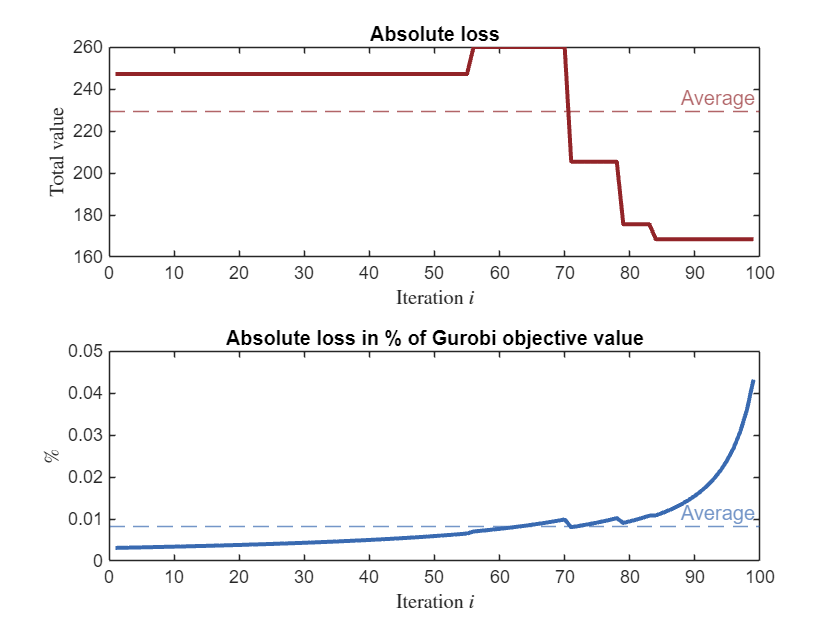

% Tiles for plot
tiledlayout(2,1);
% Move to the next plot tile
nexttile
plot(1:1:length(runtime_gurobi), loss, 'Color', gurobi_color, LineWidth=2); hold on
yline(mean(loss),'--','Average', Color=gurobi_color); hold off
title('Absolute loss');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('Total value', 'Interpreter','latex');
nexttile
plot(1:1:length(runtime_sedumi), loss./objective_gurobi, 'Color', sedumi_color, LineWidth=2); hold on
yline(mean(loss./objective_gurobi),'--','Average', Color=sedumi_color); hold off
title('Absolute loss in % of Gurobi objective value');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('\%', 'Interpreter', 'latex');

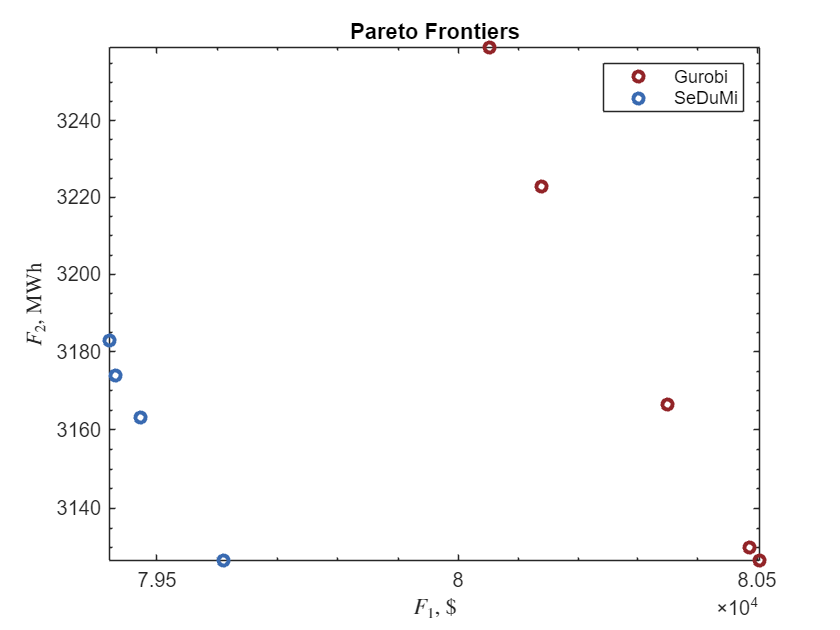

% Pareto front
figure();
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2),'o', 'MarkerSize', 5, 'Color', gurobi_color, 'LineWidth', 2); hold on
loglog(cost_sedumi(:, 1), cost_sedumi(:, 2), 'o', 'MarkerSize', 5, 'Color', sedumi_color, 'LineWidth', 2); hold off
title('Pareto Frontiers');
legend('Gurobi', 'SeDuMi');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

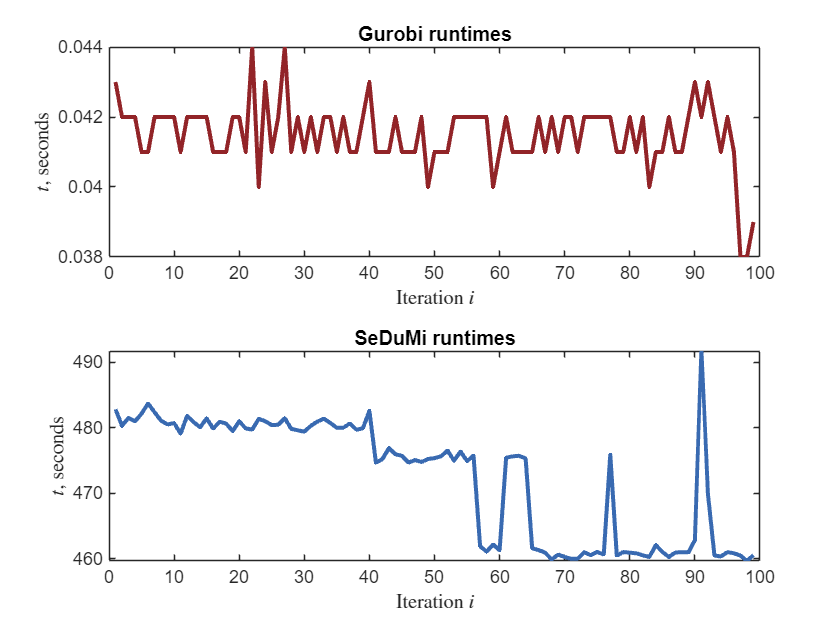

% Tiles for plot
tiledlayout(2,1);
% Move to the next plot tile
nexttile
plot(1:1:length(runtime_gurobi), runtime_gurobi, 'Color', gurobi_color, LineWidth=2);
title('Gurobi runtimes');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');
nexttile
plot(1:1:length(runtime_sedumi), runtime_sedumi, 'Color', sedumi_color, LineWidth=2);
title('SeDuMi runtimes');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');

## Gurobi: influence of penalty

% Span for uniform weights
span_pen = 0.01:0.01:0.999;
% Span for penalties
pens = [0, 25, 250];

% Placeholder variables
cost_gurobi_pen = zeros(length(span), 2);


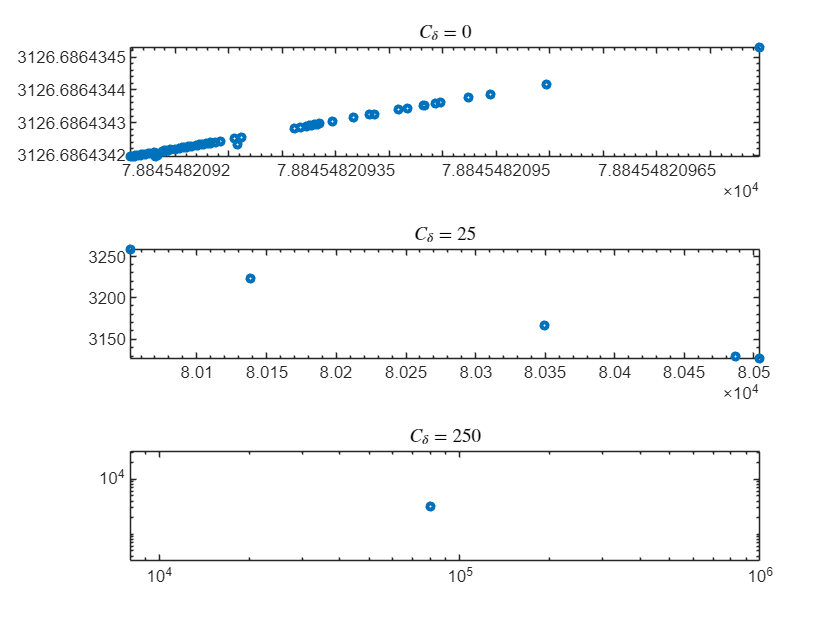

Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb34e6789
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 81983.675820
Presolve removed 274 rows a

% Plot graph in process
tiledlayout(length(pens), 1)

% Do a full front for every penalty
for i = 1:length(pens)
    alpha = pens(i);
    for j = 1:length(span_pen)
        w2 = span_pen(j);
        w1 = 1 - w2;
        network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
        network.Q_biobj = network.Q * w1;
        result_gurobi = solve_gurobi(network);
        [cost_gurobi_pen(j, 1), cost_gurobi_pen(j, 2)] = objective_values(network, alpha, result_gurobi.x);
    end  
    nexttile
    loglog(cost_gurobi_pen(:, 1), cost_gurobi_pen(:, 2), 'o', 'MarkerSize', 3, 'LineWidth', 2)
    title(['$C_\delta = ', num2str(alpha), '$'], 'Interpreter', 'latex');
end

## Gurobi: Weights

span_lin = 0.01:0.01:0.99;
cost_gurobi_lin = zeros(length(span), 2);
for i = 1:length(span)
    w2 = span_lin(i);
    w1 = 1 - w2;
    fprintf('Iteration %d: w1=%d, w2=%d\n', i, w1, w2);
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi_lin(i, 1), cost_gurobi_lin(i, 2)] = objective_values(network, alpha, result_gurobi.x);
end

Iteration 1: w1=9.900000e-01, w2=1.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf4396694
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.940001e+11
Presolve removed 259 rows a

Iteration 2: w1=9.800000e-01, w2=2.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa25474e2
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.880001e+11
Presolve removed 259 rows a

Iteration 3: w1=9.700000e-01, w2=3.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5cd6c1b9
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.820001e+11
Presolve removed 259 rows a

Iteration 4: w1=9.600000e-01, w2=4.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf3a19ead
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.760001e+11
Presolve removed 259 rows a

Iteration 5: w1=9.500000e-01, w2=5.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x20f22a7e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 1e+04]
  QObjective range [6e-04, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.700001e+11
Presolve removed 259 rows a

Iteration 6: w1=9.400000e-01, w2=6.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x1f24e081
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.640001e+11
Presolve removed 259 rows a

Iteration 7: w1=9.300000e-01, w2=7.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5b6b9000
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.580001e+11
Presolve removed 259 rows a

Iteration 8: w1=9.200000e-01, w2=8.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x58bd2df2
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.520001e+11
Presolve removed 259 rows a

Iteration 9: w1=9.100000e-01, w2=9.000000e-02


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9fc957ac
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.460001e+11
Presolve removed 259 rows a

Iteration 10: w1=9.000000e-01, w2=1.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc2270a0c
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.400001e+11
Presolve removed 259 rows a

Iteration 11: w1=8.900000e-01, w2=1.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x77859c7e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [6e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.340001e+11
Presolve removed 259 rows a

Iteration 12: w1=8.800000e-01, w2=1.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc88cc85d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.280001e+11
Presolve removed 259 rows a

Iteration 13: w1=8.700000e-01, w2=1.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9e61290e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.220001e+11
Presolve removed 259 rows a

Iteration 14: w1=8.600000e-01, w2=1.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x772ad8e1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.160001e+11
Presolve removed 259 rows a

Iteration 15: w1=8.500000e-01, w2=1.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x2fd27811
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 9e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.100001e+11
Presolve removed 259 rows a

Iteration 16: w1=8.400000e-01, w2=1.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xd12d1190
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.040001e+11
Presolve removed 259 rows a

Iteration 17: w1=8.300000e-01, w2=1.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf2360ac7
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.980001e+11
Presolve removed 259 rows a

Iteration 18: w1=8.200000e-01, w2=1.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xd17243ac
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.920001e+11
Presolve removed 259 rows a

Iteration 19: w1=8.100000e-01, w2=1.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x7d1cea6c
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.860001e+11
Presolve removed 259 rows a

Iteration 20: w1=8.000000e-01, w2=2.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x3649f430
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.800001e+11
Presolve removed 259 rows a

Iteration 21: w1=7.900000e-01, w2=2.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x26ff2d64
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.740001e+11
Presolve removed 259 rows a

Iteration 22: w1=7.800000e-01, w2=2.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xed86331e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.680001e+11
Presolve removed 259 rows a

Iteration 23: w1=7.700000e-01, w2=2.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa4ff4330
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.620001e+11
Presolve removed 259 rows a

Iteration 24: w1=7.600000e-01, w2=2.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb7c56c7d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.560001e+11
Presolve removed 259 rows a

Iteration 25: w1=7.500000e-01, w2=2.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xe340f760
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 8e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.500001e+11
Presolve removed 259 rows a

Iteration 26: w1=7.400000e-01, w2=2.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xef22b750
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.440001e+11
Presolve removed 259 rows a

Iteration 27: w1=7.300000e-01, w2=2.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0b76e0f1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [5e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.380001e+11
Presolve removed 259 rows a

Iteration 28: w1=7.200000e-01, w2=2.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf89544e5
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.320001e+11
Presolve removed 259 rows a

Iteration 29: w1=7.100000e-01, w2=2.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x41ed7c61
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.260001e+11
Presolve removed 259 rows a

Iteration 30: w1=7.000000e-01, w2=3.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x57d2196f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.200001e+11
Presolve removed 259 rows a

Iteration 31: w1=6.900000e-01, w2=3.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x28768dba
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.140001e+11
Presolve removed 259 rows a

Iteration 32: w1=6.800000e-01, w2=3.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9226f2ce
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.080001e+11
Presolve removed 259 rows a

Iteration 33: w1=6.700000e-01, w2=3.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x31578f9a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.020001e+11
Presolve removed 259 rows a

Iteration 34: w1=6.600000e-01, w2=3.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x82a9fd08
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 7e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.960001e+11
Presolve removed 259 rows a

Iteration 35: w1=6.500000e-01, w2=3.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x854c06a7
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.900001e+11
Presolve removed 259 rows a

Iteration 36: w1=6.400000e-01, w2=3.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x73acd02a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.840001e+11
Presolve removed 259 rows a

Iteration 37: w1=6.300000e-01, w2=3.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x419a16d4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.780001e+11
Presolve removed 259 rows a

Iteration 38: w1=6.200000e-01, w2=3.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf2654af4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.720001e+11
Presolve removed 259 rows a

Iteration 39: w1=6.100000e-01, w2=3.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x265d625d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.660001e+11
Presolve removed 259 rows a

Iteration 40: w1=6.000000e-01, w2=4.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xd4dc8e8e
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.600001e+11
Presolve removed 259 rows a

Iteration 41: w1=5.900000e-01, w2=4.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9e705e72
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.540001e+11
Presolve removed 259 rows a

Iteration 42: w1=5.800000e-01, w2=4.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xbdc1151f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.480000e+11
Presolve removed 259 rows a

Iteration 43: w1=5.700000e-01, w2=4.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0221f3fd
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [4e-04, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.420000e+11
Presolve removed 259 rows a

Iteration 44: w1=5.600000e-01, w2=4.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x98804e59
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.360000e+11
Presolve removed 259 rows a

Iteration 45: w1=5.500000e-01, w2=4.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x2d5dcdca
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 6e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.300000e+11
Presolve removed 259 rows a

Iteration 46: w1=5.400000e-01, w2=4.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x8319bbb4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.240000e+11
Presolve removed 259 rows a

Iteration 47: w1=5.300000e-01, w2=4.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xe465871d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.180000e+11
Presolve removed 259 rows a

Iteration 48: w1=5.200000e-01, w2=4.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x00da9621
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.120000e+11
Presolve removed 259 rows a

Iteration 49: w1=5.100000e-01, w2=4.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x4019dc2c
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.060000e+11
Presolve removed 259 rows a

Iteration 50: w1=5.000000e-01, w2=5.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf1924f73
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.000000e+11
Presolve removed 259 rows a

Iteration 51: w1=4.900000e-01, w2=5.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb88feea1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.940000e+11
Presolve removed 259 rows a

Iteration 52: w1=4.800000e-01, w2=5.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xdb25c689
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.880000e+11
Presolve removed 259 rows a

Iteration 53: w1=4.700000e-01, w2=5.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa591a303
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.820000e+11
Presolve removed 259 rows a

Iteration 54: w1=4.600000e-01, w2=5.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xf0288bcc
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.760000e+11
Presolve removed 259 rows a

Iteration 55: w1=4.500000e-01, w2=5.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5e779d42
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 5e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.700000e+11
Presolve removed 259 rows a

Iteration 56: w1=4.400000e-01, w2=5.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x3608f6cb
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 4e+03]
  QObjective range [3e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.640000e+11
Presolve removed 259 rows a

Iteration 57: w1=4.300000e-01, w2=5.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x01a3e982
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [9e-03, 4e+03]
  QObjective range [3e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.580000e+11
Presolve removed 259 rows a

Iteration 58: w1=4.200000e-01, w2=5.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa40f1fd3
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [3e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.520000e+11
Presolve removed 259 rows a

Iteration 59: w1=4.100000e-01, w2=5.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa6eb7f66
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [3e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.460000e+11
Presolve removed 259 rows a

Iteration 60: w1=4.000000e-01, w2=6.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5efd6d75
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.400000e+11
Presolve removed 259 rows a

Iteration 61: w1=3.900000e-01, w2=6.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0f73e357
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.340000e+11
Presolve removed 259 rows a

Iteration 62: w1=3.800000e-01, w2=6.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x5479b296
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.280000e+11
Presolve removed 259 rows a

Iteration 63: w1=3.700000e-01, w2=6.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x42610007
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.220000e+11
Presolve removed 259 rows a

Iteration 64: w1=3.600000e-01, w2=6.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x8adc61fd
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.160000e+11
Presolve removed 259 rows a

Iteration 65: w1=3.500000e-01, w2=6.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9ba78d7b
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 4e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.100000e+11
Presolve removed 259 rows a

Iteration 66: w1=3.400000e-01, w2=6.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x7cbe101b
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 3e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.040000e+11
Presolve removed 259 rows a

Iteration 67: w1=3.300000e-01, w2=6.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc4a34535
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [7e-03, 3e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.980000e+11
Presolve removed 259 rows a

Iteration 68: w1=3.200000e-01, w2=6.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x31e49620
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.920000e+11
Presolve removed 259 rows a

Iteration 69: w1=3.100000e-01, w2=6.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x170450d9
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.860000e+11
Presolve removed 259 rows a

Iteration 70: w1=3.000000e-01, w2=7.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc9f755e5
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.800000e+11
Presolve removed 259 rows a

Iteration 71: w1=2.900000e-01, w2=7.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x32afed07
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.740000e+11
Presolve removed 259 rows a

Iteration 72: w1=2.800000e-01, w2=7.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xa17f7f13
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.680000e+11
Presolve removed 259 rows a

Iteration 73: w1=2.700000e-01, w2=7.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x75e2d679
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.620000e+11
Presolve removed 259 rows a

Iteration 74: w1=2.600000e-01, w2=7.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x3a681495
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.560000e+11
Presolve removed 259 rows a

Iteration 75: w1=2.500000e-01, w2=7.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xefea506a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 3e+03]
  QObjective range [2e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.500000e+11
Presolve removed 259 rows a

Iteration 76: w1=2.400000e-01, w2=7.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x606a2527
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.440000e+11
Presolve removed 259 rows a

Iteration 77: w1=2.300000e-01, w2=7.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x8af998df
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [5e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.380000e+11
Presolve removed 259 rows a

Iteration 78: w1=2.200000e-01, w2=7.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xc35c3c7d
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.320000e+11
Presolve removed 259 rows a

Iteration 79: w1=2.100000e-01, w2=7.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9fdf75a0
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.260000e+11
Presolve removed 258 rows a

Iteration 80: w1=2.000000e-01, w2=8.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x189ff6df
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.200000e+11
Presolve removed 258 rows a

Iteration 81: w1=1.900000e-01, w2=8.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x032bbbc1
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.140000e+11
Presolve removed 258 rows a

Iteration 82: w1=1.800000e-01, w2=8.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x43f58d22
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-03, 2e+03]
  QObjective range [1e-04, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.080000e+11
Presolve removed 258 rows a

Iteration 83: w1=1.700000e-01, w2=8.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x2661a342
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 2e+03]
  QObjective range [1e-04, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.020000e+11
Presolve removed 258 rows a

Iteration 84: w1=1.600000e-01, w2=8.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xdb62795a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 2e+03]
  QObjective range [1e-04, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 9.600002e+10
Presolve removed 258 rows a

Iteration 85: w1=1.500000e-01, w2=8.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9458ab24
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 2e+03]
  QObjective range [9e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 9.000002e+10
Presolve removed 258 rows a

Iteration 86: w1=1.400000e-01, w2=8.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x0bffaa8f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 1e+03]
  QObjective range [9e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 8.400001e+10
Presolve removed 258 rows a

Iteration 87: w1=1.300000e-01, w2=8.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x7cf099ab
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [3e-03, 1e+03]
  QObjective range [8e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 7.800001e+10
Presolve removed 258 rows a

Iteration 88: w1=1.200000e-01, w2=8.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb3912f74
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 1e+03]
  QObjective range [7e-05, 1e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 7.200001e+10
Presolve removed 258 rows a

Iteration 89: w1=1.100000e-01, w2=8.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x05fa8636
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 1e+03]
  QObjective range [7e-05, 9e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 6.600001e+10
Presolve removed 258 rows a

Iteration 90: w1=1.000000e-01, w2=9.000000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xb8f11320
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 1e+03]
  QObjective range [6e-05, 8e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 6.000001e+10
Presolve removed 258 rows a

Iteration 91: w1=9.000000e-02, w2=9.100000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x311bbbe4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 9e+02]
  QObjective range [6e-05, 7e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 5.400001e+10
Presolve removed 258 rows a

Iteration 92: w1=8.000000e-02, w2=9.200000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x9eba9ac8
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-03, 8e+02]
  QObjective range [5e-05, 6e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.800001e+10
Presolve removed 258 rows a

Iteration 93: w1=7.000000e-02, w2=9.300000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x10bafc1f
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-03, 7e+02]
  QObjective range [4e-05, 6e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 4.200001e+10
Presolve removed 258 rows a

Iteration 94: w1=6.000000e-02, w2=9.400000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xef4c35a4
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-03, 6e+02]
  QObjective range [4e-05, 5e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.600001e+10
Presolve removed 258 rows a

Iteration 95: w1=5.000000e-02, w2=9.500000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x75da90f8
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-03, 5e+02]
  QObjective range [3e-05, 4e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 3.000001e+10
Presolve removed 258 rows a

Iteration 96: w1=4.000000e-02, w2=9.600000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x845a619b
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [8e-04, 4e+02]
  QObjective range [2e-05, 3e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 2.400001e+10
Presolve removed 258 rows a

Iteration 97: w1=3.000000e-02, w2=9.700000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x19126365
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [6e-04, 3e+02]
  QObjective range [2e-05, 2e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.800001e+10
Presolve removed 269 rows a

Iteration 98: w1=2.000000e-02, w2=9.800000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0x37689dec
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [4e-04, 2e+02]
  QObjective range [1e-05, 2e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 1.200000e+10
Presolve removed 269 rows a

Iteration 99: w1=1.000000e-02, w2=9.900000e-01


Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2519926
Set parameter Threads to value 1
Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Gurobi Optimizer version 11.0.2 build v11.0.2rc0 (win64 - Windows 11.0 (22631.2))

CPU model: AMD Ryzen 9 3900X 12-Core Processor, instruction set [SSE2|AVX|AVX2]
Thread count: 12 physical cores, 24 logical processors, using up to 1 threads

Academic license 2519926 - for non-commercial use only - registered to al___@hu-berlin.de
Optimize a model with 275 rows, 102 columns and 477 nonzeros
Model fingerprint: 0xe9f7513a
Model has 18 quadratic objective terms
Variable types: 42 continuous, 60 integer (60 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [2e-04, 1e+02]
  QObjective range [6e-06, 8e-05]
  Bounds range     [1e+00, 1e+00]
  RHS range        [9e-01, 7e+02]
Found heuristic solution: objective 6.000004e+09
Presolve removed 269 rows a

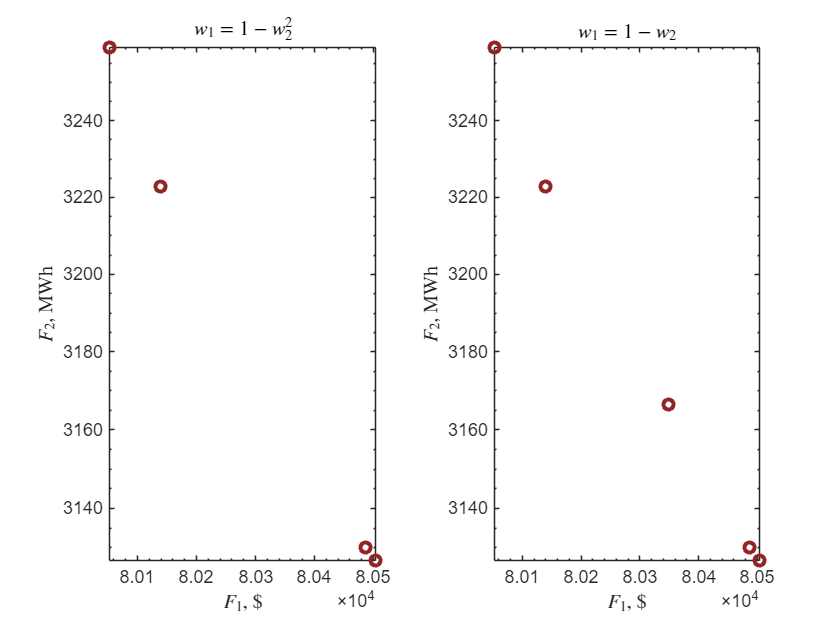

tiledlayout(1, 2)
nexttile
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2),'o', 'MarkerSize', 5, 'Color', gurobi_color, 'LineWidth', 2);
title('$w_1 = 1 - w_2^2$', 'Interpreter','latex');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');
nexttile
loglog(cost_gurobi_lin(:, 1), cost_gurobi_lin(:, 2), 'o', 'MarkerSize', 5, 'Color', gurobi_color, 'LineWidth', 2);
title('$w_1 = 1 - w_2$', 'Interpreter','latex');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

## Wind and solar generation plots (24H)

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

x = linspace(1, 24, 24);
wind_power = zeros(1, 24);
solar_power = zeros(1, 24);
for t = 1:24
    wind_power(t) = pdf(t, "wind");
    solar_power(t) = pdf(t, "solar");
end

figure()
plot(x, wind_power, Color=sedumi_color, LineWidth=2); hold on
yline(25.5,'-','Wind forecast');
yline(mean(wind_power),'--','Wind mean', Color=sedumi_color);
plot(x, solar_power, Color=gurobi_color, LineWidth=2); hold off
yline(40,'-','Solar forecast');
yline(mean(solar_power(5:20)),'--','Solar mean (5AM-8PM)', Color=gurobi_color);
title('VRE generation in 24H timespan')
legend('Wind', 'Solar');
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$g$, MW', 'Interpreter','latex');

## Example of network demand

demand_color = [83 81 84]/255;

maxgen = [455, 455, 160, 55];
starting_state = [1, 1, 0, 0];
x = linspace(1, 24, 24);
demand_profile = demand(maxgen, starting_state, 24);

figure()
plot(x, demand_profile, LineWidth=2, Color=demand_color);
title('Network demand in 24H timespan')
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');